# WLAN MAC Basics - PCAP Basics

- Generate beacon frames only

- Energy Detection threshold is hardcoded : -82dBm

- Record PCAP file for post-analysis in Wireshark

Copyright 2024-2025 The MathWorks, Inc

### Cleanup

clear;
format shortEng;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");


### General Settings

bandwidth    = 20e6;
band         = 5;
channel      = 36;
fc           = wlanChannelFrequency(channel,band);

TU              = 1024e-6;
simulationTime  = 100*TU;

### Geography

APPosition  = [0,0,0];
STAPosition = [0.5, 0.5, 0.0];

plotStations(APPosition, STAPosition, fc);

#### Create a wirelessNetworkSimulator instance

networkSimulator = wirelessNetworkSimulator.init;

### Create AP

- 802.11n

- beacon sent each 10x TU (1024us)

- AP is located at [0, 0, 0]

- AP transmits 0 dBm (make calculations easy)

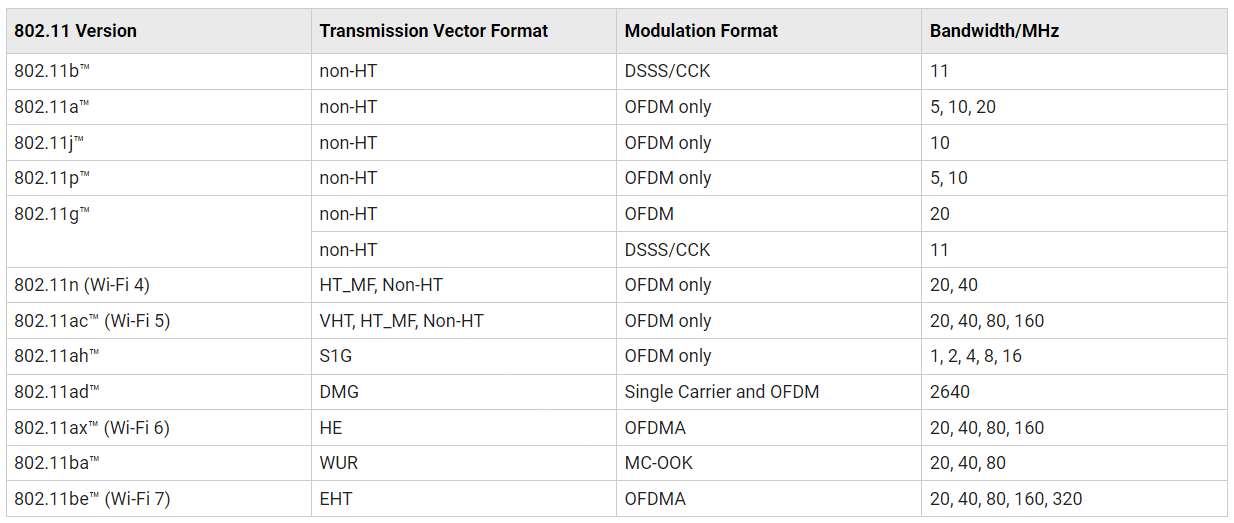

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower", 0, ...
    "TransmitGain", 0.0, ...
    "MCS",7, ...
    "BeaconInterval",inf, ...
    "InitialBeaconOffset",0, ...
    "AggregateHTMPDU",false);

AP = wlanNode(...
    "Name","AP",...
    "Position",APPosition, ...
    "DeviceConfig",APCfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Create STA

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ...
    "MCS",2, ...
    "ReceiveGain",0);

STA = wlanNode(...
    "Name","STA",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");


### Sniffer Node

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ...
    "MCS",2, ...
    "ReceiveGain",0);

SNIFFER = wlanNode(...
    "Name","SNIFFER",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Associate AP with STA

associateStations(AP,STA,"FullBufferTraffic","off");

### Create QoS Traffic

trafficType = "QoS_Traffic"

trafficType = "QoS_Traffic"

if (strcmp(trafficType, "QoS_Traffic"))

         trafficCfg = networkTrafficOnOff(...
            "OnTime", inf,...
            "OffTime", 0, ...
            "DataRate",1024*15, ...%kbps
            "PacketSize",512, ...
            "ApplicationData",uint8(0:1:255)',...
            "GeneratePacket",true);
        trafficCfg_1 = networkTrafficOnOff(...
            "OnTime", inf,...
            "OffTime", 0, ...
            "DataRate",1024*15, ...%kbps
            "PacketSize",512, ...
            "ApplicationData",uint8(0:1:255)',...
            "GeneratePacket",true);

        addTrafficSource(AP,trafficCfg,"DestinationNode",STA,"AccessCategory",0)
        addTrafficSource(AP,trafficCfg_1,"DestinationNode",STA,"AccessCategory",3)

end
nodes = [AP, STA, SNIFFER];
capturePacketsObj = hExportWLANPackets(nodes, 'pcapng', true);
addNodes(networkSimulator,{AP, STA, SNIFFER})

#### Run the simulation

run (networkSimulator,simulationTime)

### Visualize statistics

APStatistics  = statistics(AP, "all");
STAStatistics = statistics(STA);
APStatistics.MAC.AccessCategories.TransmittedDataFrames

ans =      5.0000e+000


ans =      0.0000e+000


ans =      0.0000e+000


ans =    312.0000e+000


delete(capturePacketsObj.PCAPObjList);